# Subarrays in Phased Array Antennas

This example shows how to model subarrays and perform analyses on the impacts of using subarrays.

Phased array antennas provide many benefits over traditional dish antennas. The elements of phased array antennas are easier to manufacture; the entire system suffers less from component failures; and best of all, can be electronically scanned toward different directions.

The flexibility does not come for free. Taking full advantage of a phased array requires placing steering circuitry and T/R switches behind each individual element. For applications that require large arrays with thousands or tens of thousands of elements, the cost of implementing this is too high to be practical. In addition, in many such applications, the desired performance does not require full degree of freedom from the array. With subarrays, elements are grouped into subarrays and then subarrays form the entire array. The elements are still easy to manufacture; the entire array is still robust with respect to component failures. In addition, T/R switches are only needed at each subarray, which significantly reduces the cost.

The following sections show how to model a subarray network.

## Limited Field of View (LFOV) Arrays

As the name suggests, an LFOV array only scans within a very limited window, normally less than 10 degrees. Because of that, it is possible to use subarrays and such subarrays can be placed at a spacing much larger than half of the wavelength.

The simplest way to construct an array with subarrays is to contiguously tile the subarray. The following code snippet constructs a 64-element ULA consists of eight 8-element ULAs. Within each subarray, the elements are spaced by half wavelength. Note that there is no steering capability inside each subarray so the array can only be steered using subarrays.

fc = 60e9;
c = 3e8;
hele = phased.CosineAntennaElement;
N = 64;
Nsubarray = 8;
hsubarray = phased.ULA(N/Nsubarray,0.5*c/fc,"Element",hele);

ha = phased.ReplicatedSubarray("Subarray",hsubarray,...
    "GridSize",[1 Nsubarray])

ha =   phased.ReplicatedSubarray with properties:

            Subarray: [1×1 phased.ULA]
              Layout: 'Rectangular'
            GridSize: [1 8]
         GridSpacing: 'Auto'
    SubarraySteering: 'None'

Next, compare the radiation pattern of this array to the radiation pattern of a 64-element ULA with no subarrays.

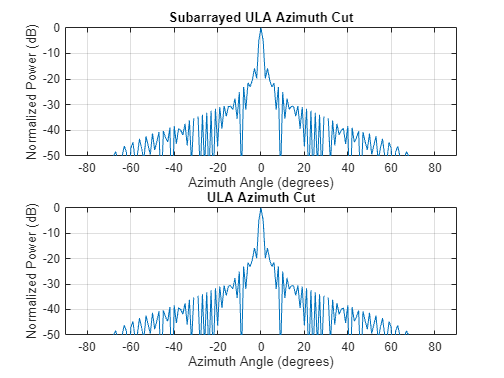

href = phased.ULA(N,0.5*c/fc,"Element",hele);
subplot(2,1,1), pattern(ha,fc,-180:180,0,"Type","powerdb",...
    "CoordinateSystem","rectangular","PropagationSpeed",c); 
title("Subarrayed ULA Azimuth Cut"); axis([-90 90 -50 0]);
subplot(2,1,2), pattern(href,fc,-180:180,0,"Type","powerdb",...
    "CoordinateSystem","rectangular","PropagationSpeed",c); 
title("ULA Azimuth Cut"); axis([-90 90 -50 0]);

From the plot, it is clear that the two responses are identical at broadside. Note that even though the subarrays are widely spaced, there are no grating lobes in the response.

Next, steer both arrays to 2 degrees azimuth.

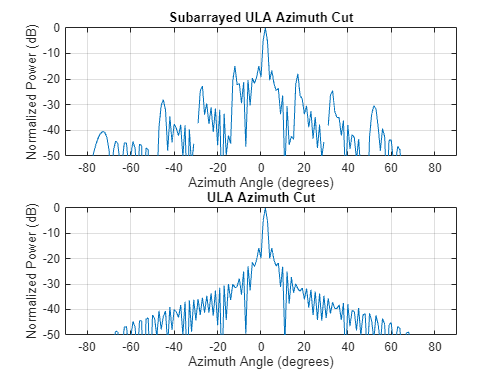

steerang = 2;
hstv = phased.SteeringVector("SensorArray",ha,"PropagationSpeed",c);
w = step(hstv,fc,steerang);
hstvref = phased.SteeringVector("SensorArray",href,"PropagationSpeed",c);
wref = step(hstvref,fc,steerang);

subplot(2,1,1), pattern(ha,fc,-180:180,0,"Type","powerdb",...
    "CoordinateSystem","rectangular","PropagationSpeed",c,"Weights",w); 
title("Subarrayed ULA Azimuth Cut"); axis([-90 90 -50 0]);
subplot(2,1,2), pattern(href,fc,-180:180,0,"Type","powerdb",...
    "CoordinateSystem","rectangular","PropagationSpeed",c,"Weights",wref); 
title("ULA Azimuth Cut"); axis([-90 90 -50 0]);

## Reference

[1] Robert Mailloux, *Electronically Scanned Arrays*, Morgan & Claypool, 2007.

*Copyright 2011-2013 The MathWorks, Inc.*